# Demo PHATE

## Load existing object

%%load('C:\Users\vanto\Documents\MATLAB\extracted_arboreal_scans 2\2019-10-03_exp_5\2019-10-03_exp_5.mat');
obj = arboreal_scan_experiment('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_thin_mask\extracted_arboreal_scans\2019-10-03_exp_5');


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


%obj = arboreal_scan_experiment('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_thin_mask\extracted_arboreal_scans\2019-10-01_exp_1');
obj.reset(); % reset previous analysis


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


## Plot ROIS and distance tree for reference

total dendritic length (-excluded branches) : 1847 um
total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

You have an exact match between values and tree structure; ROI list was not used


ans = 1

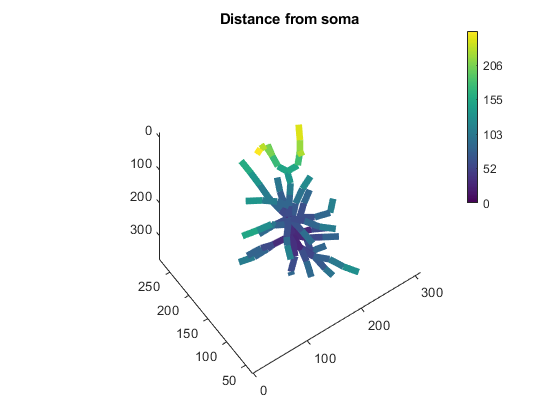

obj.plot_distance_tree();

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

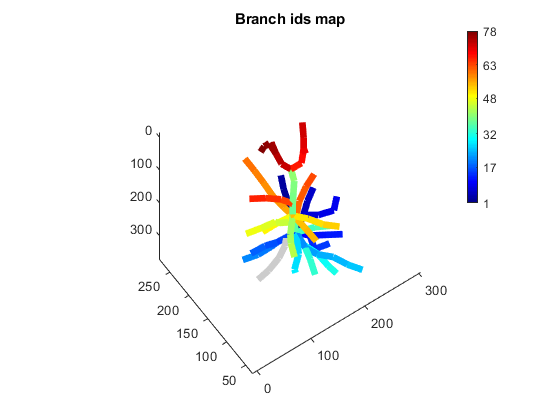

obj.ref.plot_value_tree('','','','','','','','jet');

## Create groups

obj.rescaling_method = 'by_trials_on_peaks';
obj.filter_win = [10, 0];

## Prepare Binning of the ROIs

total dendritic length (-excluded branches) : 1463 um
total dendritic length (-excluded branches) : 1847 um
total dendritic length (-excluded branches) : 1463 um
total dendritic length (-excluded branches) : 1847 um
total dendritic length (-excluded branches) : 1463 um
total dendritic length (-excluded branches) : 1847 um
total dendritic length (-excluded branches) : 1463 um
total dendritic length (-excluded branches) : 1847 um


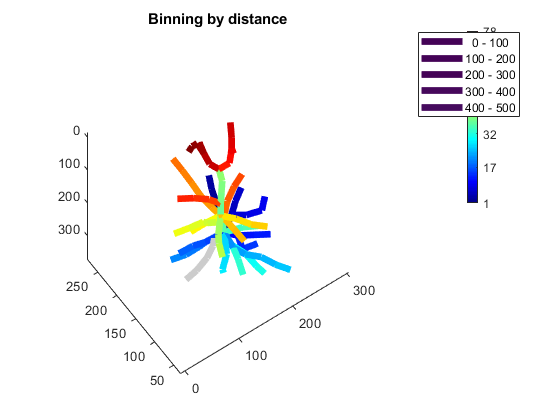

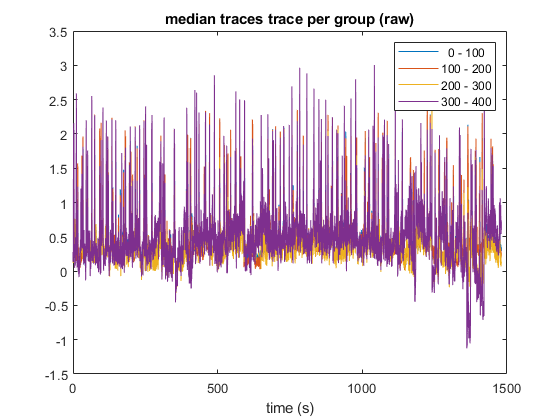

obj.prepare_binning({'distance', 100});

## Detect bAPs

Now detecting events with global pairwise correlation at least > 0.2 % 
    * Events detection is using PAIRWISE CORRELATION between all provided traces 
      Epochs of correlated changes of activity across a set % of the tree/pop will be considered as an event 


THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 88.2743%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 228 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 2events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


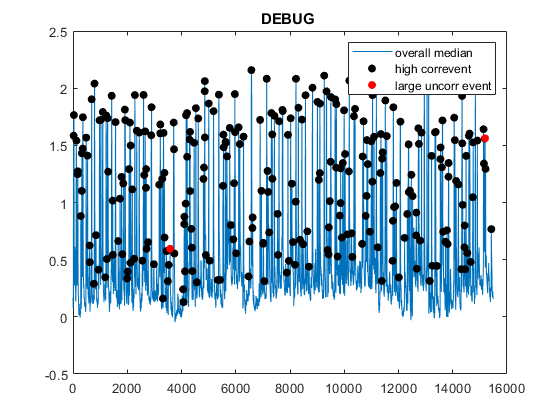

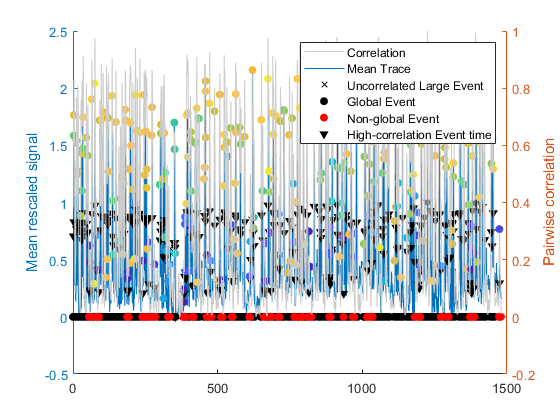

THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


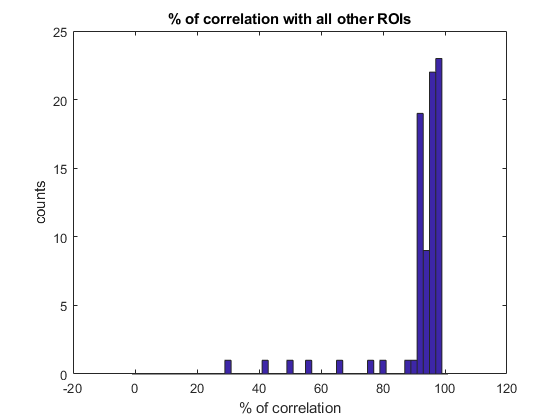

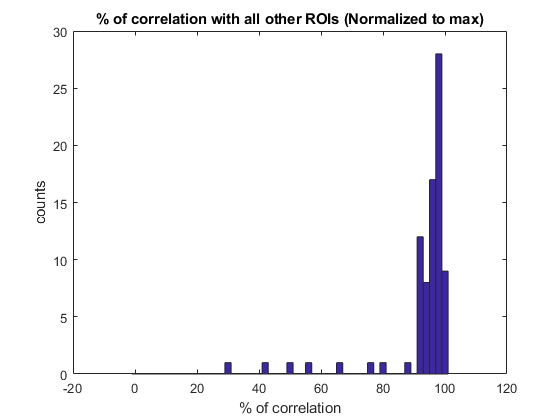

RECOVERY_THR = 0.8000

!!! ROIs 22  23 was/were excluded but seem highly correlated


spacing_factor = 1

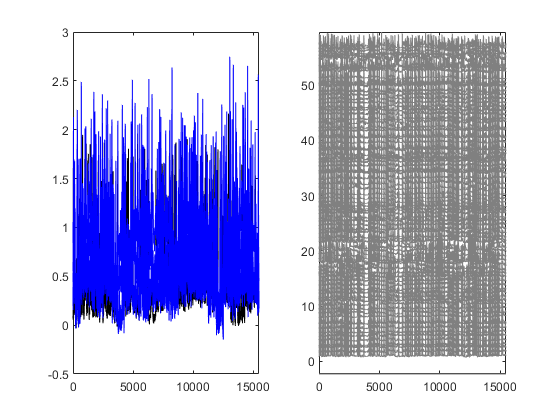

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

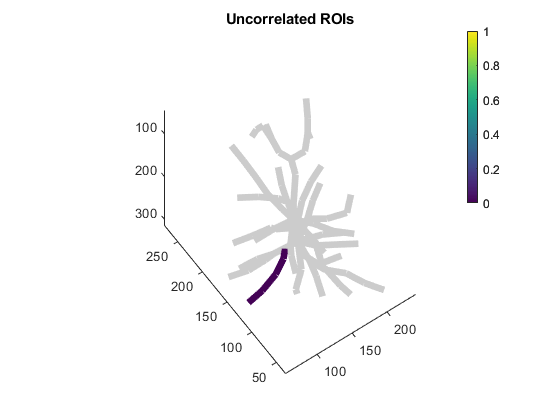

obj.find_events();

## Rescale all traces to the cell median

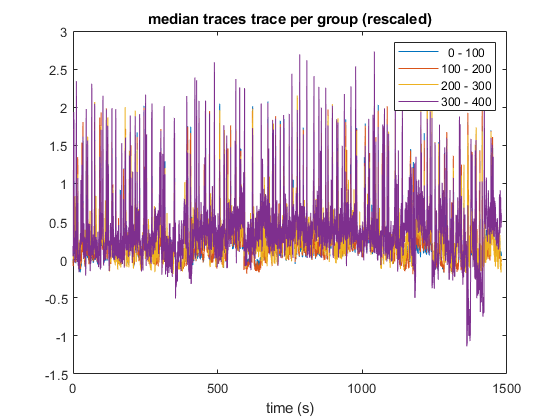

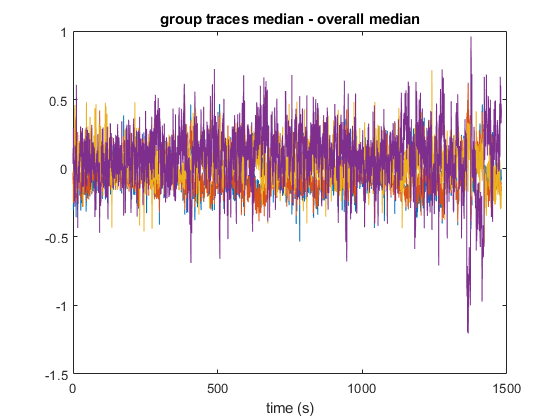

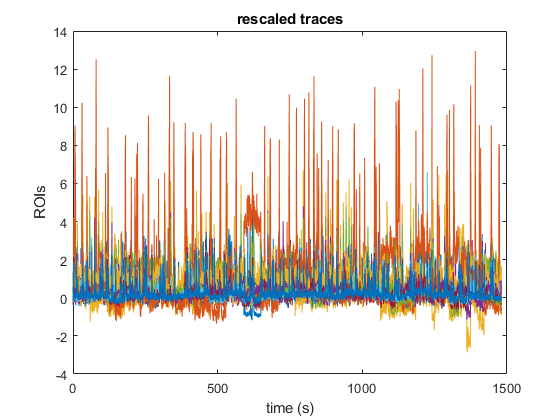

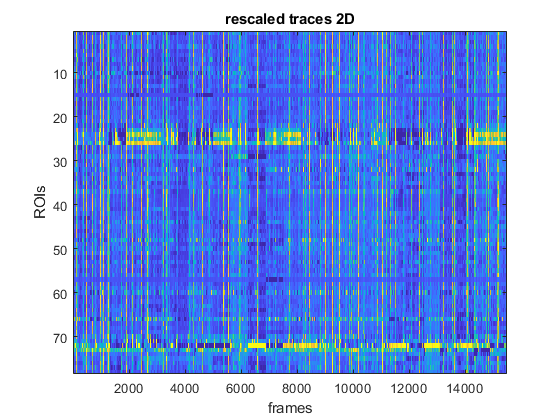

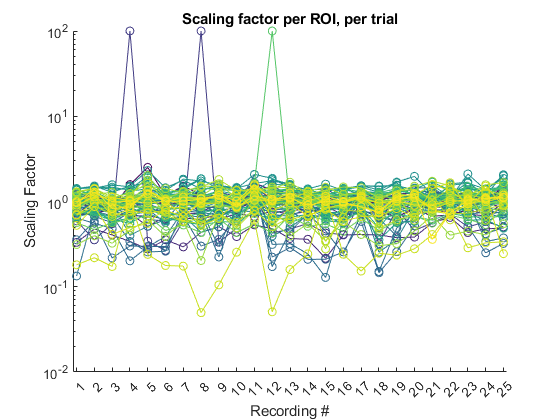

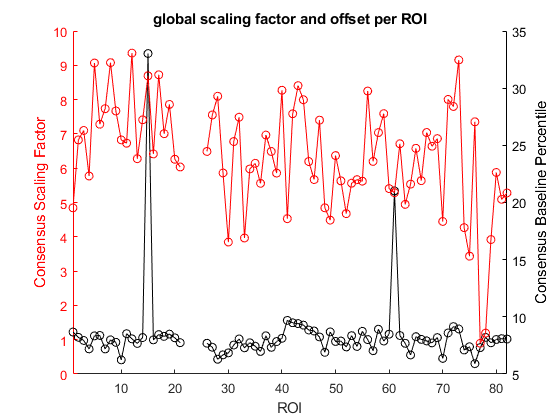

obj.rescale_traces();

## Run PHATE

Doing PCA
PCA using random SVD
PCA took 0.0051785 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 76
First iteration: k = 100
Number of samples below the threshold from 1st iter: 76
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.0077168 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 22


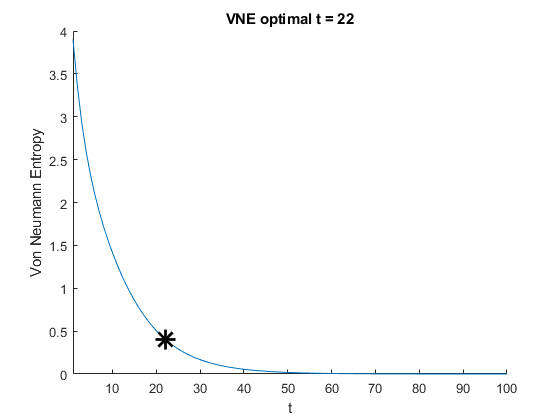

Diffusing operator
Diffusion took 0.0031368 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0034194 seconds
Doing classical MDS
CMDS took 0.0020383 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.781038       0.0663876
           1         0.35967       0.0349262         4.70493              10
           2        0.297212       0.0426935         2.70982               9
           3        0.181226       0.0549979         3.41837              11
           4        0.107964       0.0481978         1.42473              10
           5       0.0658667       0.0467622         1.27778               9
           6       0.0461419       0.0514866         0.71459               9
           7       0.031569

tree_aspect = 'simple'

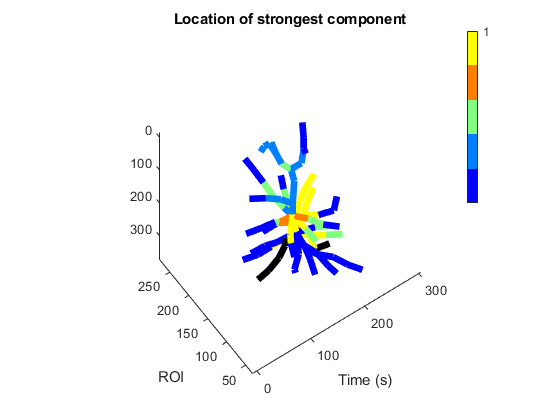

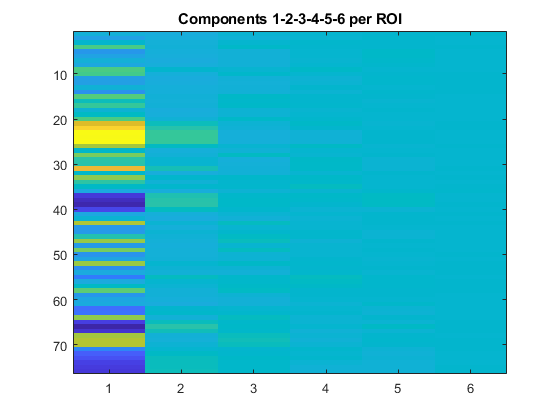

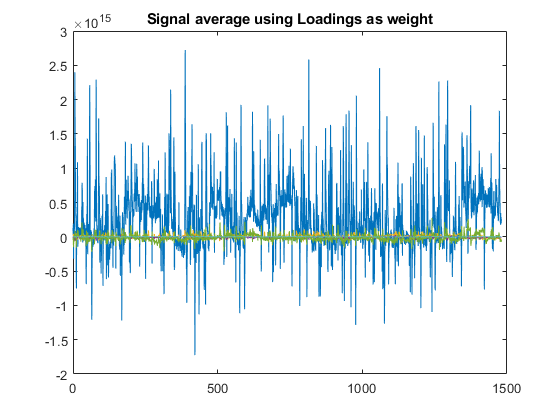

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

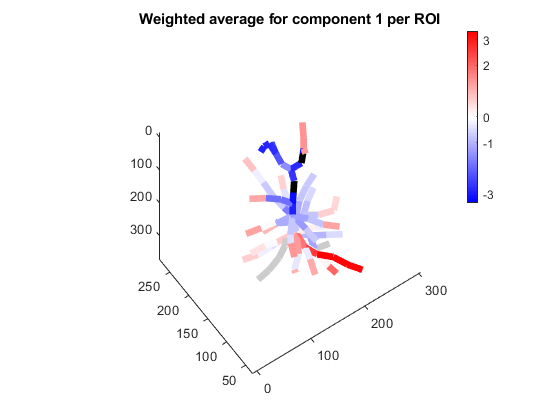

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

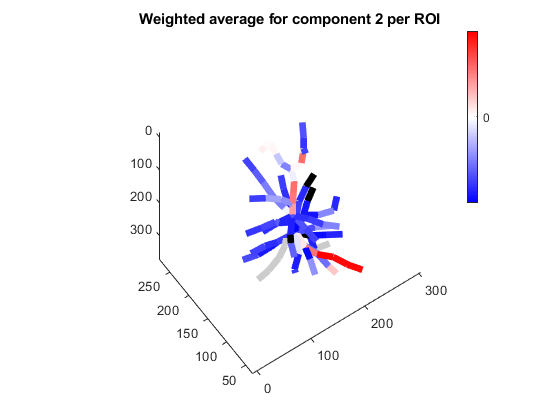

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

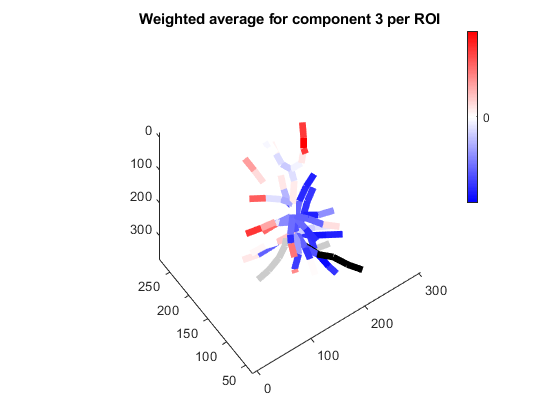

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

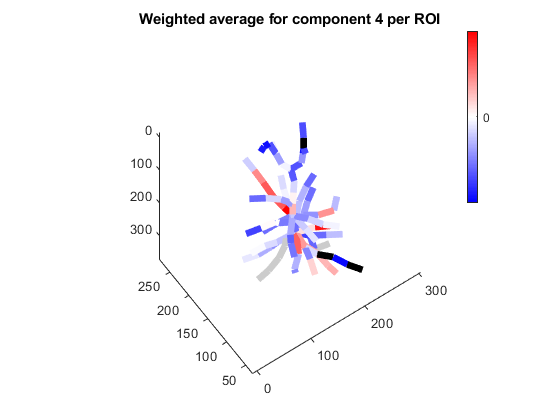

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

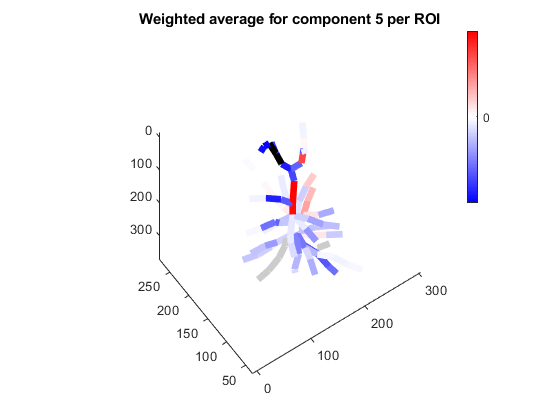

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

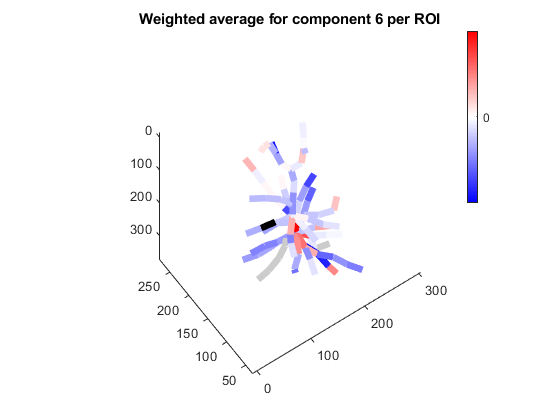

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

obj.get_dimensionality([], 'phate', 'peaks_subtracted', 12);

%obj.get_dimensionality([], 'phate', 'peaks', 6, 't', 5);

## Run clustering on phate output

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

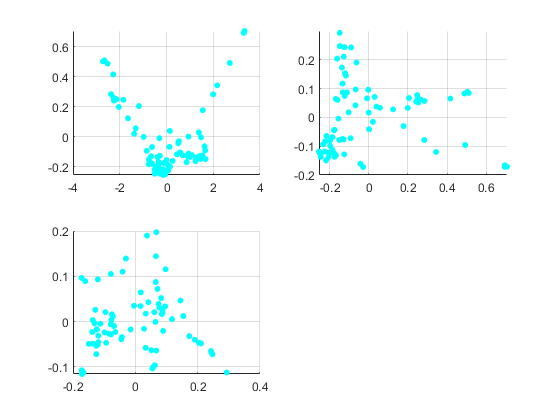

total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

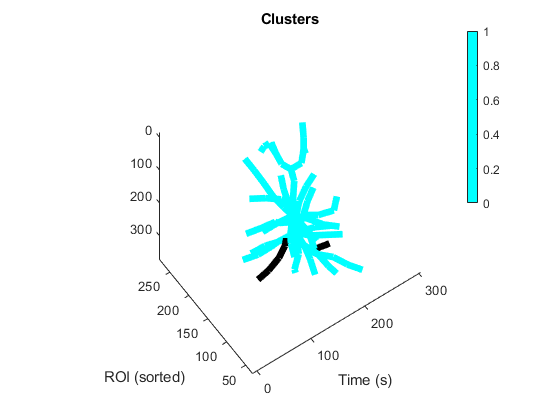

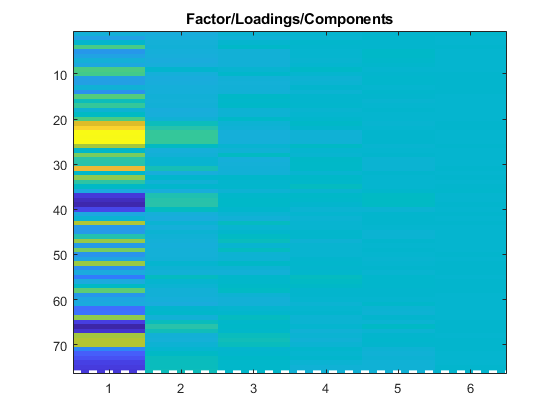

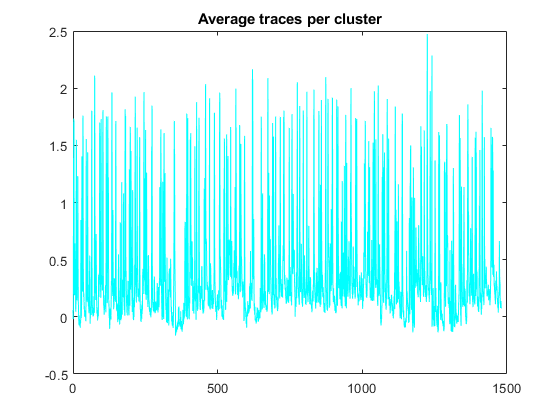

obj.cluster_factors('dbscan', -5)

## For Comparaison, get correlation matrices


	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
Using current obj.cc_mode : peaks


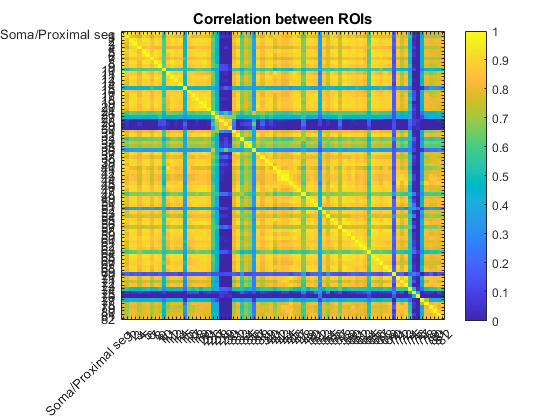

Using current obj.cc_mode : peaks
total dendritic length (-excluded branches) : 1463 um


tree_aspect = 'simple'

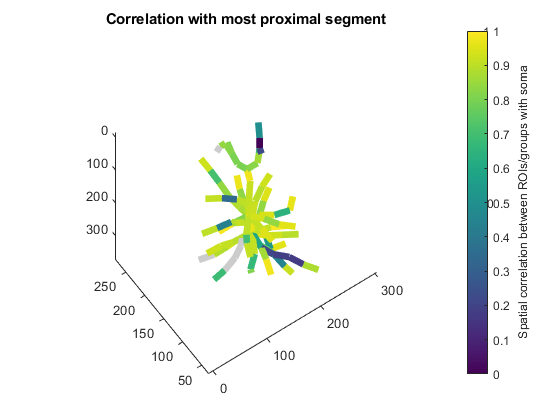

obj.get_correlations('peaks');